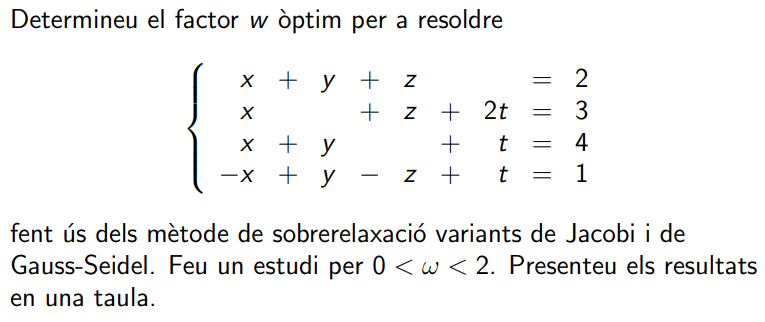

clear;

A= [1 1 1 0; -1 1 -1 1; 1 1 0 1; 1 0 1 2]; b= [2 1 4 3]'; % Movemos fila a 2 a fila 4

D= diag(diag(A));       % Diagonal
d= diag(1./diag(A));    % Inversa diagonal
L= tril(A,-1);          % Triangular inferior
U= triu(A,1);           % Triangular superior

v = zeros(10,3);
w = 0:0.2:2;
for k = 1:size(w)
    
    % JACOBI relaxacio
    C = d;
    Bsor= C*((1-w(k))*D - w(k)*(L+U));
    Csor= w(k)*C*b;

    % SEIDEL relaxacio
    CS = inv(D + w(k) *L);
    BsorS = CS*((1-w(k))*D - w(k)*U);
    csorS = w(k)*CS*b;
    
    v(k) = w(k);
    v(k) = max(abs(eig(Bsor)));
    v(k) = max(abs(eig(BsorS)));
    
end

Error using eig
Input matrix contains NaN or Inf.

format short g
v
plot(v(:,1), v(:,2))
